%(a)
xin=-1:0.001:1;
X1=fxquant(xin,4,'round','sat');
X2=fxquant(xin,4,'trunc','sat');
e1=X1-xin;
e2=X2-xin;

disp(min(e1));

   -0.1250



disp(max(e1));

    0.0620



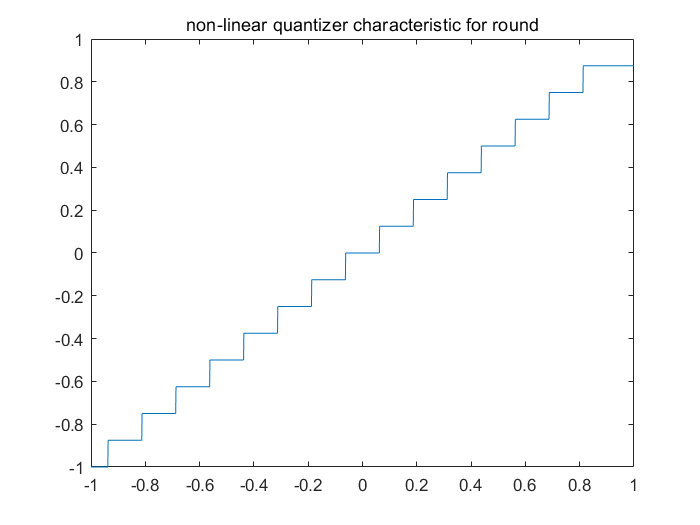

figure;
plot(xin,X1);
title('non-linear quantizer characteristic for round');


disp(min(e2));

   -0.1250



disp(max(e2));

     0



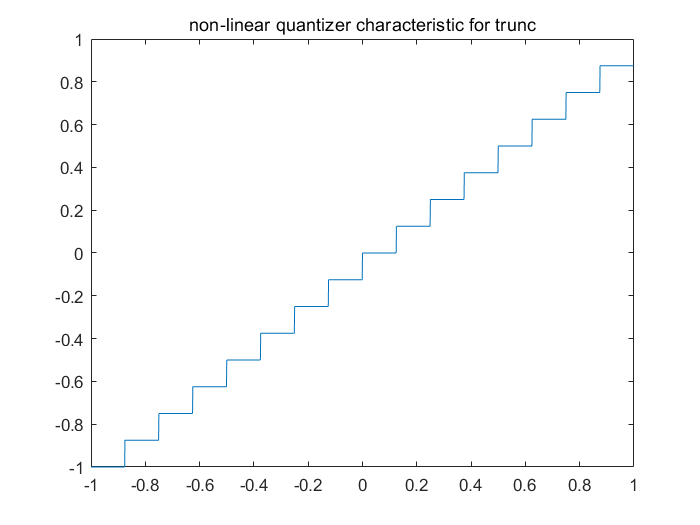

figure;
plot(xin,X2);
title('non-linear quantizer characteristic for trunc');

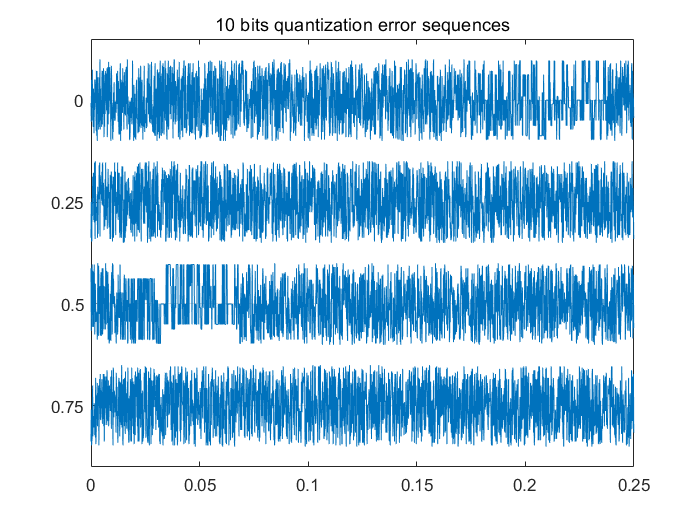


%(b)
[s,fs]=audioread('s5.wav');
s=s(1300:18800);
X1_s5_10=fxquant(s,10,'round','sat');
X1_s5_8=fxquant(s,8,'round','sat');
X1_s5_4=fxquant(s,4,'round','sat');
e1_10=X1_s5_10-s;
e1_8=X1_s5_8-s;
e1_4=X1_s5_4-s;

figure;
strips(e1_10(1:8000),2000/fs,fs);
title('10 bits quantization error sequences');

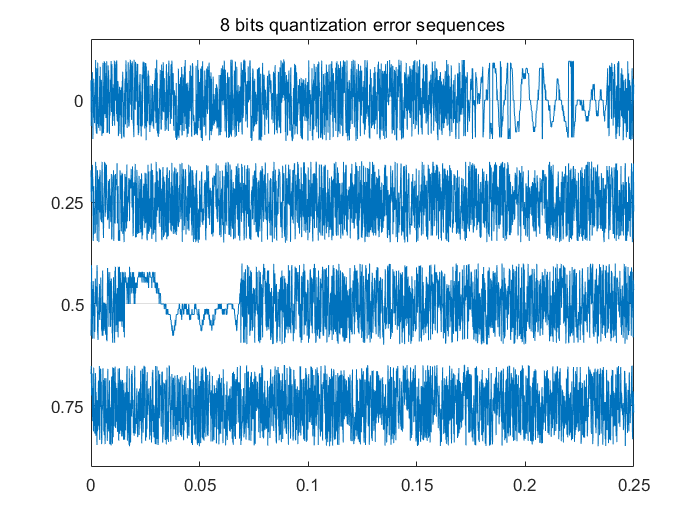

figure;
strips(e1_8(1:8000),2000/fs,fs);
title('8 bits quantization error sequences');

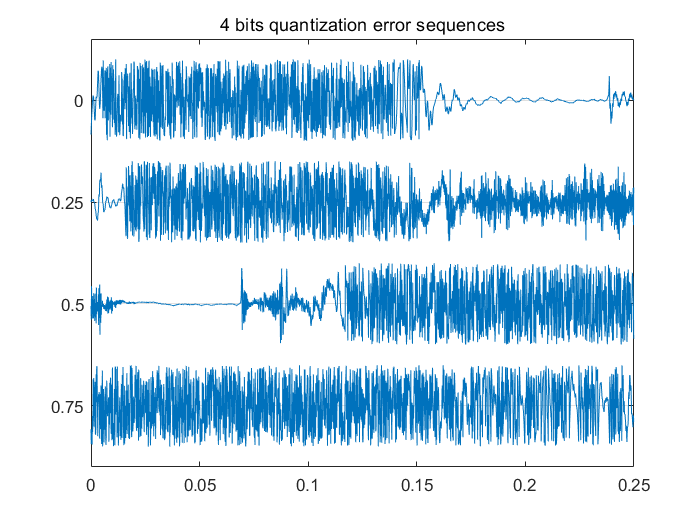

figure;
strips(e1_4(1:8000),2000/fs,fs);
title('4 bits quantization error sequences');

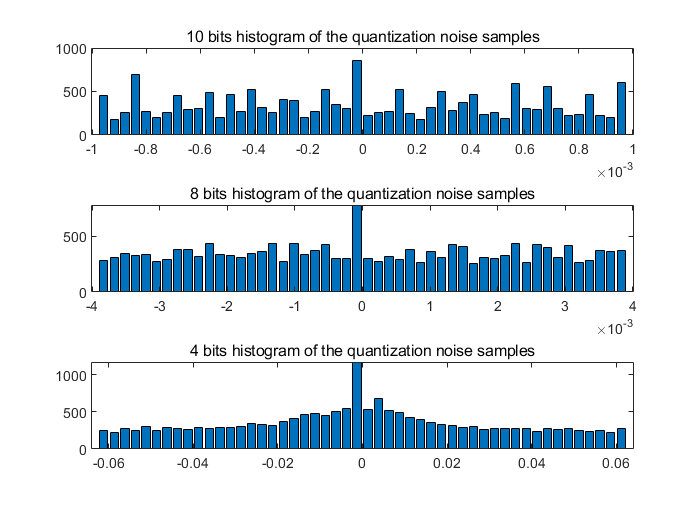


[hist10,center10]=hist(e1_10,50);
[hist8,center8]=hist(e1_8,50);
[hist4,center4]=hist(e1_4,50);

figure;
subplot(3,1,1);
bar(center10,hist10);
title('10 bits histogram of the quantization noise samples');
subplot(3,1,2);
bar(center8,hist8);
title('8 bits histogram of the quantization noise samples');
subplot(3,1,3);
bar(center4,hist4);
title('4 bits histogram of the quantization noise samples');

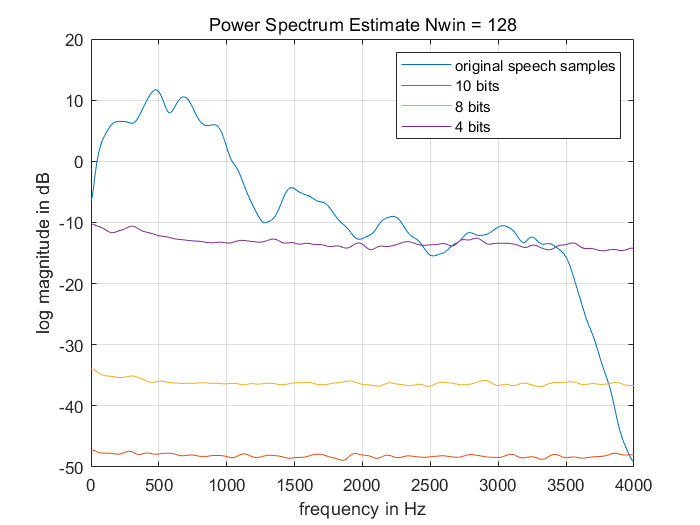


%(c)
figure;
pspect(s,fs,1024,128);
hold on;
pspect(e1_10,fs,1024,128);
hold on;
pspect(e1_8,fs,1024,128);
hold on;
pspect(e1_4,fs,1024,128);
hold on;
legend('original speech samples','10 bits','8 bits','4 bits');


[p_10,F_10]=pspect(e1_10,fs,1024,128);
[p_8,F_8]=pspect(e1_8,fs,1024,128);
difference=10*log10(p_10)-10*log10(p_8);
disp(mean(difference));

  -11.9336

